# Week 10 Data Anaylsis

Katie Foster

Load Data

data = load("EMGdataWeek10.mat");

1. Make separate plots for each condition (smiling, frowning) that show all of the trials at once. Using imagesc may be a good approach. What do you observe?

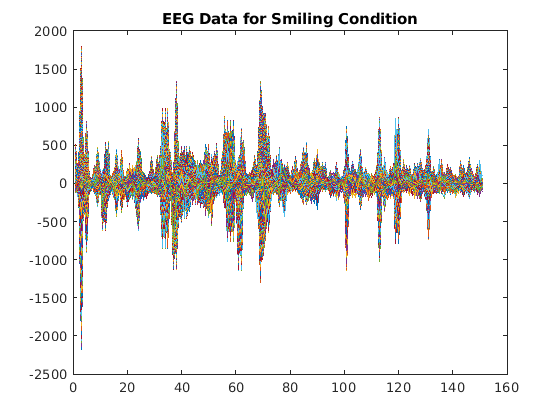

sindex = find(data.labels == "S pressed");
plot(data.data_ch1(sindex, :)); hold on;
plot(data.data_ch2(sindex, :)); hold off;
title("EEG Data for Smiling Condition");

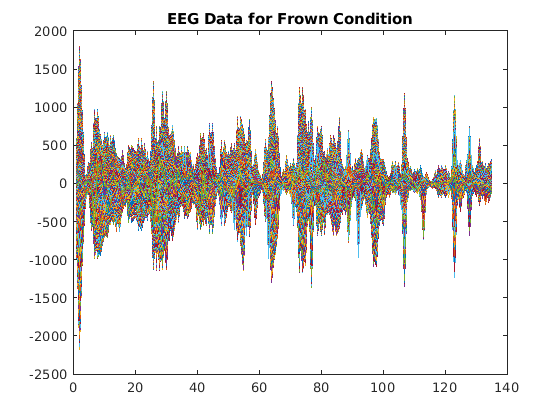

findex = find(data.labels == "F pressed");
plot(data.data_ch1(findex, :)); hold on;
plot(data.data_ch2(findex, :)); hold off;
title("EEG Data for Frown Condition");

Well that's not very helpful. Maybe I should use imagesc

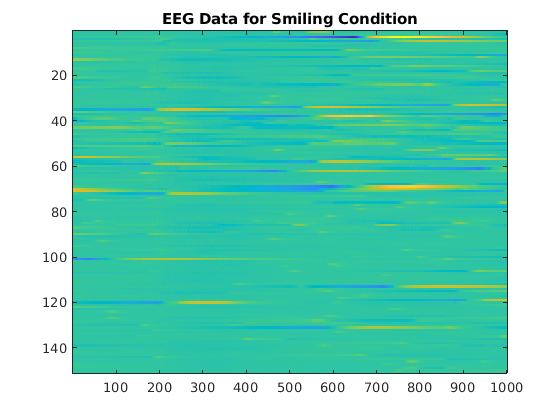

imagesc(data.data_ch1(sindex, :));
title("EEG Data for Smiling Condition");

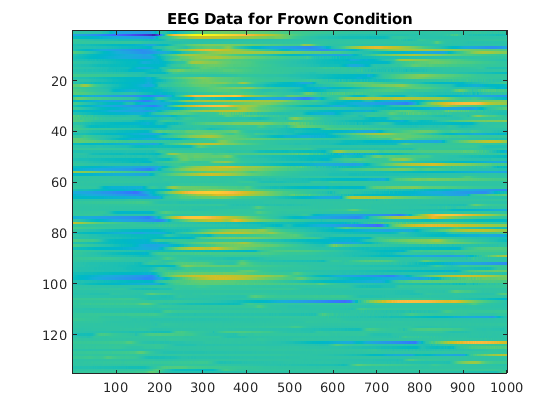


imagesc(data.data_ch1(findex, :));
title("EEG Data for Frown Condition");

I observe that there are more of the yellow and blue patches for the frown condition, which seems to indicate that there are more spikes on that graph.

2. Compare the mean time course for the two conditions by showing them on the same plot. Include separate lines to indicate 95% confidence intervals around each time course. What do you observe?

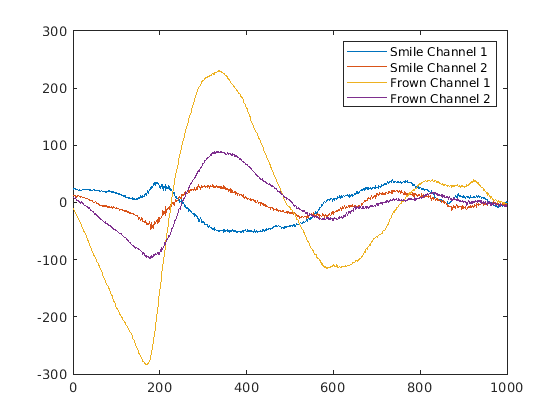

plot(mean(data.data_ch1(sindex, :))); hold on;
plot(mean(data.data_ch2(sindex, :))); 
plot(mean(data.data_ch1(findex, :))); 
plot(mean(data.data_ch2(findex, :))); hold off;
legend("Smile Channel 1", "Smile Channel 2", "Frown Channel 1", "Frown Channel 2");

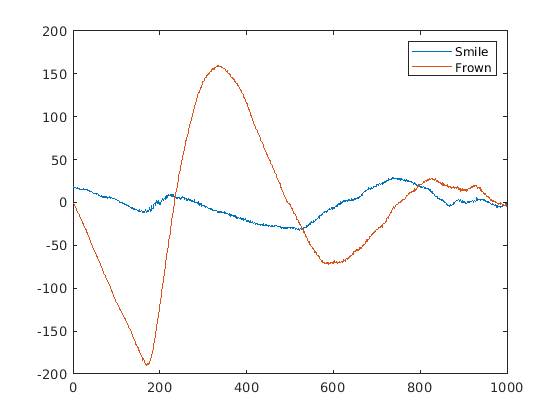

meanSmile = mean(data.data_ch1(sindex, :) + data.data_ch2(sindex, :))./2;
meanFrown = mean(data.data_ch1(findex, :) + data.data_ch2(findex, :))./2;
plot(meanSmile); hold on;
plot(meanFrown); hold off;
legend("Smile", "Frown");

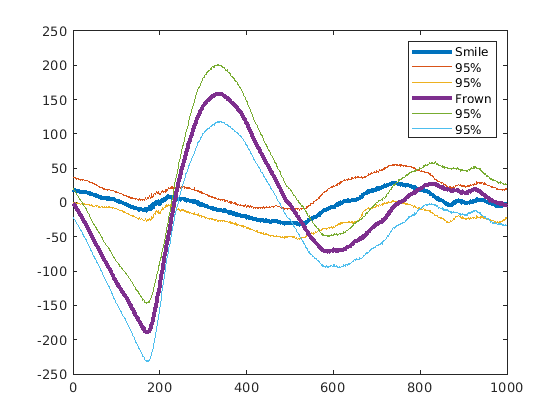

sdSmile = std((data.data_ch1(sindex, :) + data.data_ch2(sindex, :))./2, 1);
sdmnSmile = sdSmile/sqrt(length(sindex));
sdFrown = std((data.data_ch1(findex, :) + data.data_ch2(findex, :))./2, 1);
sdmnFrown = sdFrown/sqrt(length(findex));
plot(meanSmile, 'Linewidth', 3); hold on;
plot(meanSmile+2*sdmnSmile);
plot(meanSmile-2*sdmnSmile);
plot(meanFrown, 'Linewidth', 3); 
plot(meanFrown+2*sdmnFrown);
plot(meanFrown-2*sdmnFrown); hold off;
legend("Smile", "95%", "95%", "Frown", "95%", "95%");

Challenge: Determine which time periods are statistically different between the two conditions. Explain what you observe. What might we need to consider in making a comparison like this (either from a statistics or an experimental design standpoint). 

i_s = randsample(length(sindex), length(sindex), 1);
i_f = randsample(length(findex), length(findex), 1);
smile1rand = data.data_ch1(i_s,:);
meansmile1rand = mean(smile1rand);

ntrials = length(sindex);
EEGSmile = [data.data_ch1(sindex, :), data.data_ch2(sindex, :)]; %Merge EEG data from all trials.
statD = zeros(3000,1); %Empty variable to hold results.
for k=1:3000 %For each resampling,
    i=randsample(ntrials,2*ntrials,1); %... choose trials,
    rand = EEGSmile(i,:); %... create resampled EEG,
    mnA = mean(rand,1); %... create resampled ERP.
    i=randsample(ntrials,2*ntrials,1); %The, re-choose trials,
    rand = EEGSmile(i,:); %... create resampled EEG,
    mnB = mean(rand,1); %... create resampled ERP.
    mnD = mnA-mnB; %Compute differenced ERP,
    statD(k)= max(abs(mnD));%... and the statistic.
end

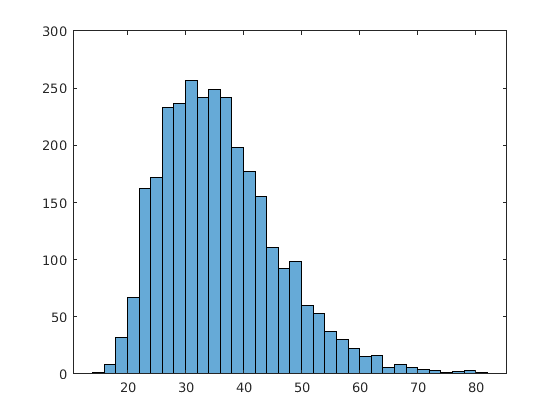

histogram(statD);